## ode45 implementation with paper's function

Basically an adaptation of the paper but without the representaiton of the trajectories.

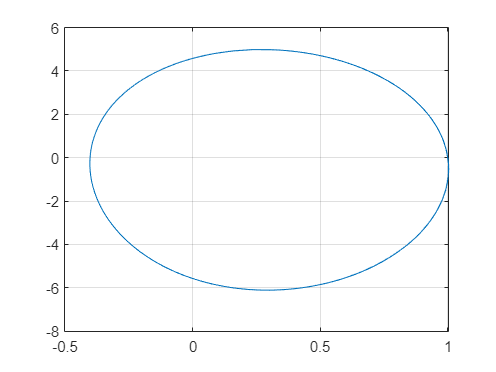

global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;

acc=0.00001; ti=0;
x0=1; y0=0;

options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
tf=ti+5;

[T, XY]= ode45cycles(ti,x0,y0,acc,2);

plot(XY(:,1),XY(:,2))
grid on

## Functions

function dz=fQsys(t, z)
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1),z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [T,XY]=ode45cycles(ti,x0,y0,acc,n)
    options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
    tf=ti+10;
    k=1+2*n;
    [T, XY]= ode45(@fQsys, [ti tf], [x0 y0], options);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=3;
    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        tf=tf+100;
        [T, XY]= ode45(@fQsys, [ti tf], [x0 y0], options);
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end
    if(count==cmax)
        ci=y_sign_change(3)+1;
        disp("can't find number of cycles")
        T=T(1:ci);
        XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
end